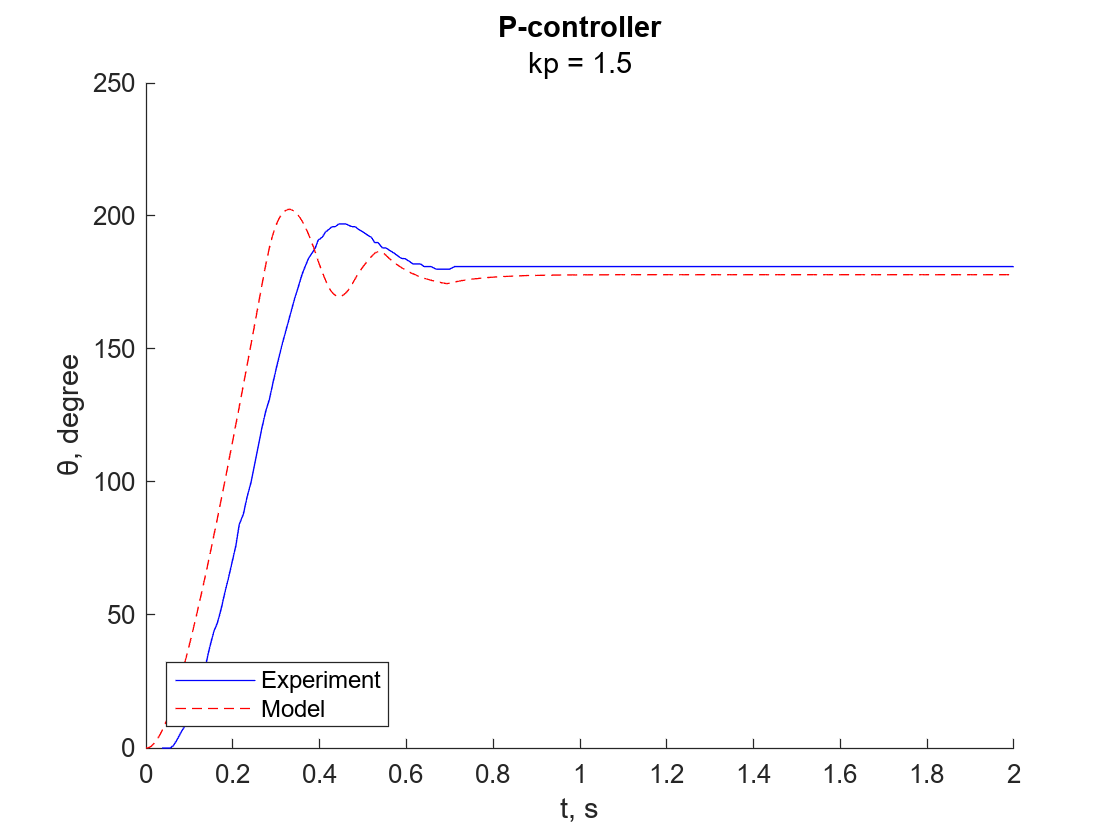

ke = 0.4987;
km = ke;
Tm = 0.0886;  
R =  8.8696;
L = 0.0047;
J = 0.0023;
target = 180;
Umin = 8.05;
M = 0.02; 
kp= 1.5;

data=readmatrix('Prop_coef_1.5.txt');
X=data(:,1);
Y=data(:,2);

xlim([0 2])
simout=sim('P_model.slx');

hold on

plot(X,Y,'b')
plot(simout.simulinkP(:,1),simout.simulinkP(:,2),'r--')

title('P-controller',{'kp = 1.5'})
xlabel('t, s')
ylabel('θ, degree')
legend('Experiment', 'Model','Location','southwest')